# EXERCISE #5 Compare Throughput of Various MLO modes and Non-MLO mode

Copyright 2024-2025 The MathWorks, Inc

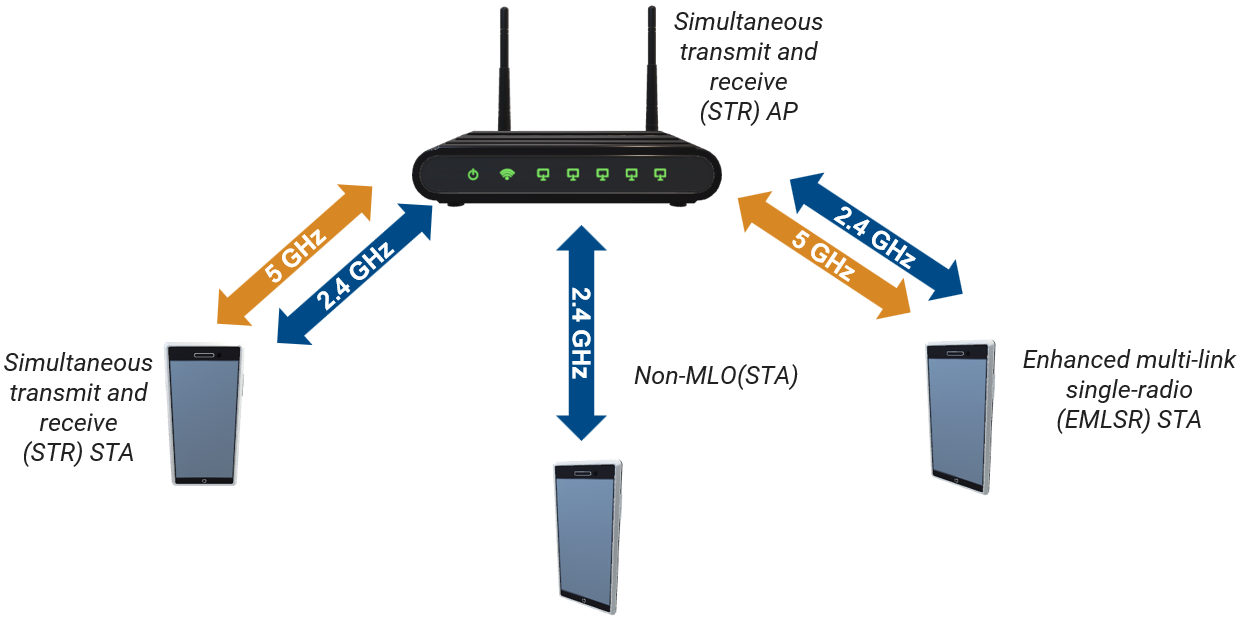

Set the seed for the random number generator to `1`. The seed value controls the pattern of random number generation. The random number generated by the seed value impacts several processes within the simulation, including backoff counter selection at the MAC layer and predicting packet reception success at the physical layer. To improve the accuracy of your simulation results after running the simulation, you can change the seed value, run the simulation again, and average the results over multiple simulations. 

Copyright 2024-2025 The MathWorks, Inc

% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
% Set simulation time as 1 Sec
simulationTime = 1;
% Create wireless network simulator
networkSimulator = wirelessNetworkSimulator.init;

%Define positions of nodes
AP_pos  = [0,0,0];
STR_STA_pos = [10,0,0];
EMLSR_STA_pos = [0,10,0];
NON_MLO_STA_pos = [0,0,10];

% Band and channel values for each link
bandAndChannel = [2.4 1;5 36];


apLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 4, ...
    "NumSpaceTimeStreams", 4, ...
    "MCS",3);

apMLDCfg = wlanMultilinkDeviceConfig("Mode","AP", ...
    "LinkConfig",apLinkCfg);

apNode = wlanNode("Position",AP_pos, ...
    "Name","AP", ...
    "DeviceConfig",apMLDCfg);

staSTRLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 2, ...
    "NumSpaceTimeStreams", 2, ...
    "MCS",3);

staSTRMLDCfg = wlanMultilinkDeviceConfig("Mode","STA", ...
    "LinkConfig",staSTRLinkCfg);

staNodes(1) = wlanNode("Position",STR_STA_pos, ...
    "Name","STR STA", ...
    "DeviceConfig",staSTRMLDCfg);

staEMLSRLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel, ...
    "NumTransmitAntennas",2, ...
    "NumSpaceTimeStreams",2, ...
    "MCS",3);

staEMLSRMLDCfg = wlanMultilinkDeviceConfig("Mode","STA", ...
    "LinkConfig",staEMLSRLinkCfg, ...
    "EnhancedMultilinkMode","EMLSR");

staNodes(2) = wlanNode("Position",EMLSR_STA_pos, ...
    "Name","EMLSR STA", ...
    "DeviceConfig",staEMLSRMLDCfg);


staDeviceConfig = wlanDeviceConfig("Mode","STA","BandAndChannel",bandAndChannel(1,:),...
    "NumTransmitAntennas",2, ...
    "NumSpaceTimeStreams",2, ...
    "MCS",3, ...
    "TransmissionFormat","EHT-SU");

staNodes(3) = wlanNode("Position",NON_MLO_STA_pos, ...
    "Name","Non-MLD STA", ...
    "DeviceConfig",staDeviceConfig);

% Create a device config object for non-MLD STA
nodes = [apNode staNodes];
% Associate the STAs to AP MLD and configure uplink full buffer traffic
% Use associateStations() function to associate STAs with AP
% Hint: Type "doc wlannode.associatestations" in the MATLAB Command Window, and see the "Syntax" section.
associateStations(apNode,staNodes,FullBufferTraffic="UL");

% Add channel model to the simulator
channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn);

% Add nodes to network simulator
addNodes(networkSimulator,nodes);

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(nodes,simulationTime);

% Run the simulation
run(networkSimulator,simulationTime);

% Calculate throughput at STAs
staThroughputs = throughput(perfViewerObj,[staNodes(:).ID]);
apPacketLossRatio = packetLossRatio(perfViewerObj,[staNodes(:).ID])

apPacketLossRatio =      0.0000e+000     0.0000e+000     0.0000e+000


staAverageReceiveLatency = averageReceiveLatency(perfViewerObj,[staNodes(:).ID])

staAverageReceiveLatency =      0.0000e+000     0.0000e+000     0.0000e+000


## Plot the STA throughputs as a bar graph

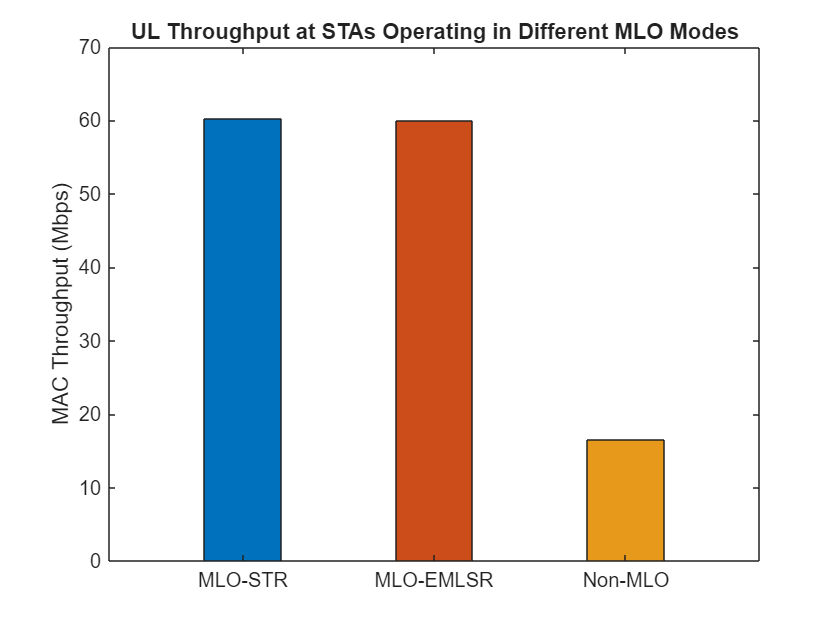

fig = figure;
matlab.graphics.internal.themes.figureUseDesktopTheme(fig);
% Names of the bars
modes = ["MLO-STR" "MLO-EMLSR" "Non-MLO"];
% Plot a bar graph specifying the width of bar (40% of available bar width)
% and face color
b = bar(modes,staThroughputs,0.4,'FaceColor','flat');
% RGB triplets for second and third bars
b.CData(2,:) = [0.8 0.3 0.1];
b.CData(3,:) = [0.9 0.6 0.1];
title("UL Throughput at STAs Operating in Different MLO Modes");
ylabel("MAC Throughput (Mbps)");

stats = statistics(staNodes, "all");
stats(2)

ans = struct with fields:
    Name: "EMLSR STA"
      ID: 3.0000e+000
     App: [1×1 struct]
     MAC: [1×1 struct]
     PHY: [1×1 struct]
    Mesh: [1×1 struct]


stats(2).MAC.Link(1).SuccessfulDataTransmissions

ans =      1.8360e+003


stats(2).MAC.Link(2).SuccessfulDataTransmissions

ans =      3.1620e+003


*Copyright 2024 The MathWorks, Inc.*